CRG_st.name='CRG';
CRG_st.lat=45.6644;
CRG_st.lon=-121.001;
CRG_st.alt=178;
CRG_st.env='con';
CRG_st.footp='RB';


CRG_rd=read_betsy('CRG1_head',CRG_st.name);

datevec(CRG_rd.Time(1))

ans =         1993           7           2           0           0           0

datevec(CRG_rd.Time(end))

ans =         2005           4           1           0           0           0

prctile(CRG_rd.U_S,[5 50 95])

ans =    34.5885   62.6950   92.3600

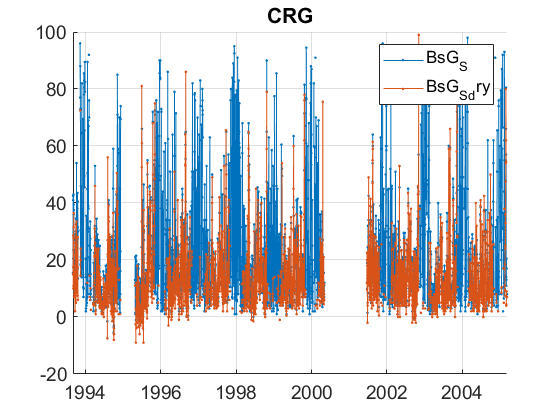

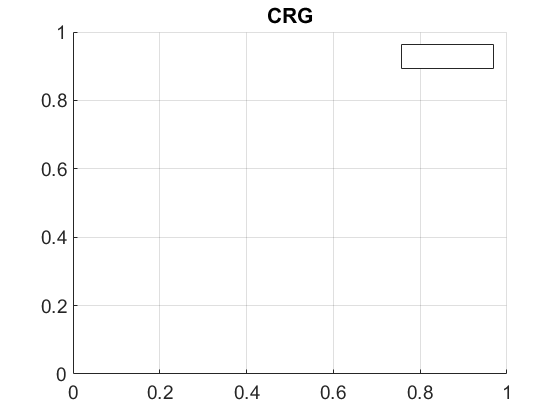

plotFigControl(CRG_rd,CRG_st.name);

% 1 size cut, ok
% sc: ok, cycle max in winter, few negatives




% % lambdaSC=[450;550;700]*ones(1,4);
% % lambdaAE=[467;530;660]*ones(1,4);
% % CRG_cal=compute_exp_SSA(CRG_rd,lambdaSC, lambdaAE);
% % plotFigControl_cal(CRG_cal);

%Questions:
%problems:
% higher minimal values at the beginning of the measurements in 1993
% hole May 2000-June 2001: no data or databank problem ?



CRG_tr=CRG_rd;
CRG_tr.y=year(CRG_tr.Time);

CRG_tr=CRG_tr(1:end-1,:);
% begin at the beginning of a year: 1994
%end: 2004
P=timerange('1994-01-01','2005-01-01');
CRG_tr=CRG_tr(P,:);

names=fieldnames(CRG_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    CRG_tr.(N{i})=[];
end


% dry: a lot of missing in winter

CRG_result= all_trend_STN(CRG_tr,CRG_st); 

CRG_result_D=CRG_result;